# EEL 3135 Lab 2

## 1.1 Step 1: Template Database 


clear all 
close all 
clc 
%--------------------------------------
% Comparing Waveforms With Real Numbers 
%--------------------------------------
f=[1:7.5:98.5];                                      % Hint: this should be a vector or array
fs=1000;                                   % Scalar Value 
dt=1/fs;                                      % Scalar Value 
t=[0:dt:3-dt];                                    % Time Vector 
A=1;
    
for N=1:length(f)
    TemplateDataBase(N,:)=A*cos(2*pi*f(N)*t);  % Creates Database where f is specifically indexed by N
end 

1. Report exactly what is being stored within in ’f’ and the dimesions. 

'f' is an array of the frequency of the wave, stepping 7.5Hz with 14 values from 1 to 98.5, 1x14

2. Report exactly what is being stored in ‘Fs’ and the dimensions.

Frequency of sampling, which is 1000Hz described above, 1x1. 

3. Describe what is in ”TemplateDataBase” and the dimensions.

It is an array of waves, starting at N=1, making as many waves as there are frequencies within the array of f and samples 3000 points, it is 14x3000

## 1.2 Step 2: Create Your Own Method to Compare with a Known Cosine Signal

A=1; 
f_GT=8.5;
Signal_GT=A*cos(2*pi*f_GT*t);                           % Ground Truth Signal 
   
for N=1:length(f)                                       % Iterate through the known signal and your database 
    SignalCompare(N)=sum((Signal_GT-TemplateDataBase(N,:)).^2) % Store a single value metric that provides context on the strength of the match or comparision.
    disp(SignalCompare(N))
end 

SignalCompare = 2.9980e+03

   2.9980e+03



SignalCompare = 1.0e+03 *

    2.9980         0


     0



SignalCompare = 1.0e+03 *

    2.9980         0    2.9980


        2998



SignalCompare = 1.0e+03 *

    2.9980         0    2.9980    3.0000


   3.0000e+03



SignalCompare = 1.0e+03 *

    2.9980         0    2.9980    3.0000    2.9980


        2998



SignalCompare = 1.0e+03 *

    2.9980         0    2.9980    3.0000    2.9980    3.0000


   3.0000e+03



SignalCompare = 1.0e+03 *

    2.9980         0    2.9980    3.0000    2.9980    3.0000    2.9980


   2.9980e+03



SignalCompare = 1.0e+03 *

    2.9980         0    2.9980    3.0000    2.9980    3.0000    2.9980    3.0000


   3.0000e+03



SignalCompare = 1.0e+03 *

    2.9980         0    2.9980    3.0000    2.9980    3.0000    2.9980    3.0000    2.9980


   2.9980e+03



SignalCompare = 1.0e+03 *

    2.9980         0    2.9980    3.0000    2.9980    3.0000    2.9980    3.0000    2.9980    3.0000


   3.0000e+03



SignalCompare = 1.0e+03 *

    2.9980         0    2.9980    3.0000    2.9980    3.0000    2.9980    3.0000    2.9980    3.0000    2.9980


   2.9980e+03



SignalCompare = 1.0e+03 *

    2.9980         0    2.9980    3.0000    2.9980    3.0000    2.9980    3.0000    2.9980    3.0000    2.9980    3.0000


   3.0000e+03



SignalCompare = 1.0e+03 *

    2.9980         0    2.9980    3.0000    2.9980    3.0000    2.9980    3.0000    2.9980    3.0000    2.9980    3.0000    2.9980


   2.9980e+03



SignalCompare = 1.0e+03 *

    2.9980         0    2.9980    3.0000    2.9980    3.0000    2.9980    3.0000    2.9980    3.0000    2.9980    3.0000    2.9980    3.0000


   3.0000e+03



1. What is the value of fGT: 8.5Hz

2. What are the dimensions of SignalGT: 1x3000 vector, a cosine wave with 1V amplitude, 8.5Hz frequency and 0 phase.

3. What was the method you developed to compare the two signals? Why did you use this method. Discuss your logic in detail (More than 4 sentences). The logic doesn’t have to be correct but I am looking for your thought process. Report and provide plots.

I chose to do the sum of the square of the differences, because otherwise the positive and negative halves of the waves would cancel out. The individual 3000 points could be anywhere between 0 and 4 an d the sum shows the avg. Closer to 0 means closer fit, further means more difference.

## 1.3 Step 3: Comparing Energy Between the Signals

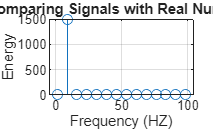

% Part 1

f_gt = f(2);
SignalGT=A*cos(2*pi*f_gt*t);

for N=1:length(f)                                       % Iterate through the known signal and your database 
    SignalEnergy(N)=sum(SignalGT .* TemplateDataBase(N,:)); % Store a single value metric that provides context on the strength of the match or comparision.
end 

figure 
stem(f,SignalEnergy)
grid on
xlabel('Frequency (HZ)')
ylabel('Energy')
title('Comparing Signals with Real Numbers')

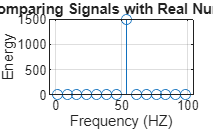


figure

% Part 2

f_gt = f(8);
SignalGT=A*cos(2*pi*f_gt*t);

for N=1:length(f)                                       % Iterate through the known signal and your database 
    SignalEnergy(N)=sum(SignalGT .* TemplateDataBase(N,:)); % Store a single value metric that provides context on the strength of the match or comparision.
end 

stem(f,SignalEnergy)
grid on
xlabel('Frequency (HZ)')
ylabel('Energy')
title('Comparing Signals with Real Numbers')


% Part 3

deviations = [0.1, 0.25, 0.5, 1, 2, 3, 5]

deviations =     0.1000    0.2500    0.5000    1.0000    2.0000    3.0000    5.0000


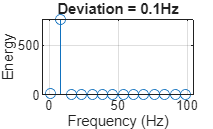

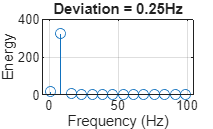

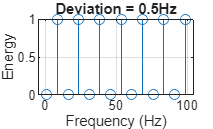

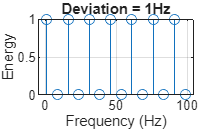

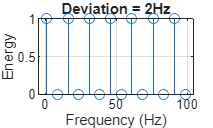

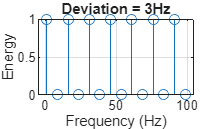

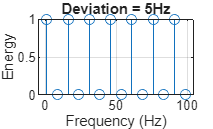

for i = 1:length(deviations) 
    f_gt = f(2) + deviations(i);
    SignalGT=A*cos(2*pi*f_gt*t);
    for N = 1:length(f)
        SignalEnergy(N)=abs(sum(SignalGT .* TemplateDataBase(N,:)));
    end
    figure
    stem(f, SignalEnergy)
    grid on
    xlabel('Frequency (Hz)')
    ylabel('Energy')
    title(['Deviation = ' num2str(deviations(i)) 'Hz'])
end

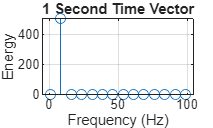


% Part 4
f_gt = f(2);
t_s = 0:1/fs:1;
SignalGTShort = A*cos(2*pi*f_gt*t_s);

for N = 1:length(f)
    SignalEnergy(N) = sum(SignalGTShort .* TemplateDataBase(N,1:length(t_s)));
end

figure
stem(f, SignalEnergy)
grid on
xlabel('Frequency (Hz)')
ylabel('Energy')
title('1 Second Time Vector')

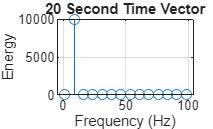


t_l=[0:dt:20-dt];                                    % Time Vector
SignalGTLong = A*cos(2*pi*f_gt*t_l);
TemplateDataBaseLong = zeros(length(f), length(t_l));

for J=1:length(f)
    TemplateDataBaseLong(J,:)=A*cos(2*pi*f(J)*t_l);  % Creates Database where f is specifically indexed by N
end 

for N = 1:length(f)
    SignalEnergy(N) = sum(SignalGTLong .* TemplateDataBaseLong(N,1:length(t_l)));
end

figure
stem(f, SignalEnergy)
grid on
xlabel('Frequency (Hz)')
ylabel('Energy')
title('20 Second Time Vector')

1. Using fGT = f(2) as your first experimental frequency. Provides the plots and described what happened. 

The peak moves to the new frequency.

2. Alter the frequency to other values within the vector f. Provides the plots and described what happened. 

The peak moves to the frequency of f_gt, as the overlap of the waves changes to the frequency of the new GT.

3. Alter the frequency to other values near the elements within the vector f but not exactly the values within the array. Start with deviations of .1 Hz, .25 Hz, .5Hz, 1 Hz, 2Hz, 3 Hz, 5Hz. Provides the plots and described what happened in great detail! (5-8 Sentences. Analyze and think about what is happening).

The plots show that at a small deviation, the peak remains around the exact match, but at a lower energy. This is likely because the frequency change is small enough to where the original frequency is still a vey close fit. However, as the deviation changes and becomes more significant this behavior also changes. When the deviation is significant, it instead makes much smaller peaks more often at a somewhat steady interval. This is probably because even though there is not a direct fit, there are still close fits that repeat at set intervals.

4. Significantly decrease and increase your time vector (1 sec, 20 seconds). Provides the plots and described what happened.

The higher frequency had a much higher peak than the lower frequency.

## 1.4 Step 4: Comparing Energy With Real and Imaginary Components

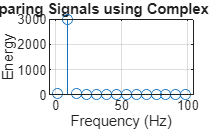

% Part 1

f_gt = f(2) ;
SignalGT = A*exp(1i*2*pi*f_gt*t);

for N=1:length(f)
    TemplateDataBaseComplex = A*exp(1i*2*pi*f(N)*t);
    SignalEnergy(N) = abs(sum(SignalGT .* conj(TemplateDataBaseComplex)));
end 

figure 
stem(f,SignalEnergy)
grid on 
title('Comparing Signals using Complex Numbers')
xlabel('Frequency (Hz)')
ylabel('Energy')

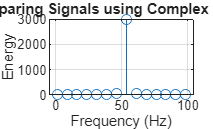


% Part 2

f_gt = f(8) ;
SignalGT = A*exp(1i*2*pi*f_gt*t);

for N=1:length(f)
    TemplateDataBaseComplex = A*exp(1i*2*pi*f(N)*t);
    SignalEnergy(N) = abs(sum(SignalGT .* conj(TemplateDataBaseComplex)));
end 

figure 
stem(f,SignalEnergy)
grid on 
title('Comparing Signals using Complex Numbers')
xlabel('Frequency (Hz)')
ylabel('Energy')


% Part 3

deviations = [0.1, 0.25, 0.5, 1, 2, 3, 5]

deviations =     0.1000    0.2500    0.5000    1.0000    2.0000    3.0000    5.0000


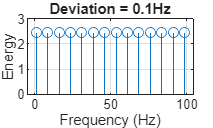

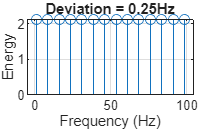

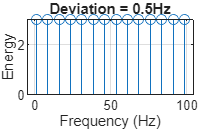

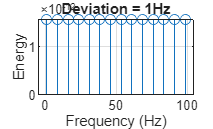

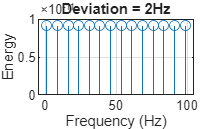

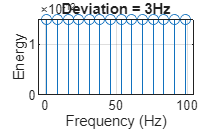

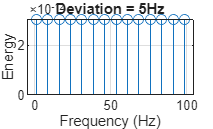

for i = 1:length(deviations) 
    f_gt = f(2) + deviations(i);
    SignalGT = A*exp(1i*2*pi*f_gt*t);
    for N = 1:length(f)
        SignalEnergy(N)=abs(sum(SignalGT .* TemplateDataBaseComplex));
    end
    figure
    stem(f, SignalEnergy)
    grid on
    xlabel('Frequency (Hz)')
    ylabel('Energy')
    title(['Deviation = ' num2str(deviations(i)) 'Hz'])
end

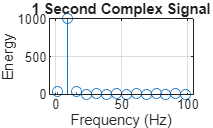


% Part 4

f_gt = f(2);
t_s = 0:1/fs:1;
SignalGTShort = A*exp(1i*2*pi*f_gt*t_s);

TemplateDataBaseShort = zeros(length(f), length(t_s));
for J=1:length(f)
    TemplateDataBaseShort(J,:)=A*exp(1i*2*pi*f(J)*t_s);  % Creates Database where f is specifically indexed by N
end 

for N = 1:length(f)
    SignalEnergy(N) = abs(sum(SignalGTShort .* conj(TemplateDataBaseShort(N,:))));
end

figure
stem(f, SignalEnergy)
grid on
xlabel('Frequency (Hz)')
ylabel('Energy')
title('1 Second Complex Signal')

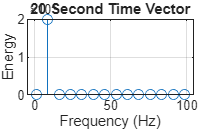


t_l=[0:dt:20-dt];                                    % Time Vector
SignalGTLong = A*exp(1i*2*pi*f_gt*t_l);

TemplateDataBaseLong = zeros(length(f), length(t_l));
for J=1:length(f)
    TemplateDataBaseLong(J,:)=A*exp(1i*2*pi*f(J)*t_l);  % Creates Database where f is specifically indexed by N
end 

for N = 1:length(f)
    SignalEnergy(N) = abs(sum(SignalGTLong .* conj(TemplateDataBaseLong(N,:))));
end

figure
stem(f, SignalEnergy)
grid on
xlabel('Frequency (Hz)')
ylabel('Energy')
title('20 Second Time Vector')

1. Using fGT = f(2) as your first experimental frequency. Provides the plots and described what happened. 

We get a peak at f(2)

2. Alter the frequency to other values within the vector f. Provides the plots and described what happened. 

The peak is now at the new fGT.

3. Alter the frequency to other values near the elements within the vector f but not exactly the values within the array. Start with deviations of .1 Hz, .25 Hz, .5Hz, 1 Hz, 2Hz, 3 Hz, 5Hz. Provides the plots and described what happened in great detail! (5-8 Sentences. Analyze and think about what is happening) 

Right off the bat we see an instant change from one peak to multiple peaks, albeit at a much, much smaller magnitude. Something unique about the complex plots is that the peaks actually rise from the 0.1Hz deviation to the 0.5Hz deviation, which may have to do with complex rotation. However, going above these small deviations will cause your peaks to crash drastically. This is seen in the plots after 0.5Hz going into magnitudes of 1/10^12. This makes sense as complex signals are more suseptible to changes in their phase than a standard signal.

4. Significantly decrease and increase your time vector (1 sec, 20 seconds). Provides the plots and described what happened.

The shorter complex signal had a much higher spike and the longer 20 second signal had a much smaller spike.